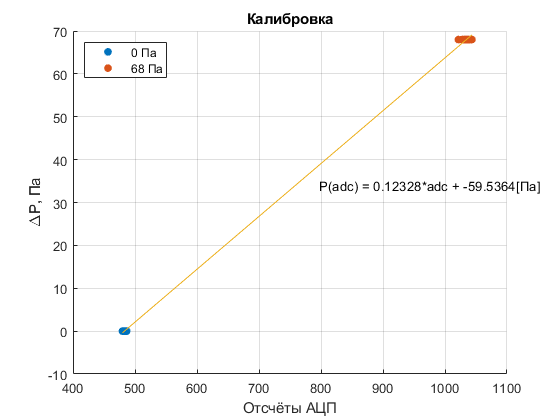


close all;
clear valuables;




%Калибровка
c00 = importdata("calibzero.txt");
c68 = importdata("calib.txt");

fclose('all');

torr00 = ones(length(c00), 1)*0;
torr68 = ones(length(c68), 1)*68;


Adc = [c00; c68];
torr = [torr00; torr68];
c = polyfit(Adc, torr, 1);

cFigure = figure('Name','Калибровка', "NumberTitle",'off');
hold all;
plot(c00, torr00, '.', 'MarkerSize',20);
plot(c68, torr68, '.', 'MarkerSize',20);

plot(Adc, polyval(c, Adc));
legend('0 Па','68 Па', 'Location','northwest');
grid on;
xlabel('Отсчёты АЦП');
ylabel('\DeltaP, Па');
title('Калибровка');
text(mean(Adc)*1.05, mean(torr), ['P(adc) = ', num2str(c(1)) , '*adc + ', num2str(c(2)), '[Па]']);
set(gcf, 'Visible', 'on');
saveas(cFigure, 'Калибровка.png');

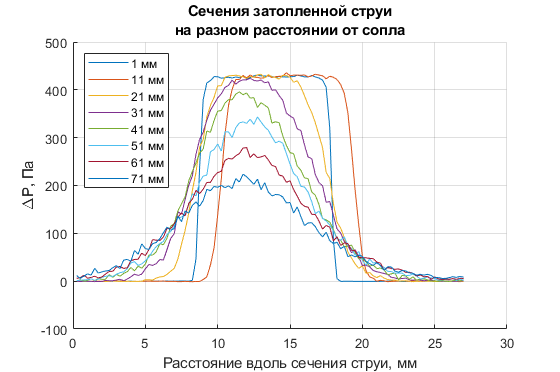


%Загрузка данных

mm01 = load("01mm.dat");
mm11 = load("11mm.dat");
mm21 = load("21mm.dat");
mm31 = load("31mm.dat");
mm41 = load("41mm.dat");
mm51 = load("51mm.dat");
mm61 = load("61mm.dat");
mm71 = load("71mm.dat");

dx = 0.25; 
x = mm01(:, 1)' * 0.25;

p01 = polyval(c, mm01(:, 2));
p11 = polyval(c, mm11(:, 2));
p21 = polyval(c, mm21(:, 2));
p31 = polyval(c, mm31(:, 2));
p41 = polyval(c, mm41(:, 2));
p51 = polyval(c, mm51(:, 2));
p61 = polyval(c, mm61(:, 2));
p71 = polyval(c, mm71(:, 2));

pressure = [p01, p11, p21, p31, p41, p51, p61, p71];
zNames = {'1 мм';'11 мм';'21 мм';'31 мм';'41 мм';'51 мм';'61 мм';'71 мм'};
z = [1, 11, 21, 31, 41, 51, 61, 71];

f2 = figure();
hold on;
grid on;
title({'Сечения затопленной струи', 'на разном расстоянии от сопла'});
ylabel('\DeltaP, Па');
xlabel('Расстояние вдоль сечения струи, мм');

for i = 1:size(pressure, 2)
    plot(x, pressure(:, i), 'DisplayName', zNames{i});
end

legend('Location', 'northwest');
saveas(f2, 'Давление.png');
set(f2, 'Visible', 'on');

%Сдвиг к центру сопла

f3 = figure();
hold on;
grid on;
title({'Центрированные сечения затопленной струи', 'на разном расстоянии от сопла'});
ylabel('\DeltaP, Па');
xlabel('Расстояние вдоль сечения струи, мм');

xCentered = zeros(size(pressure));
offset = 50;

for i = 1:size(pressure, 2)
    right = x(find(pressure(:, i) > offset, 1, 'last'));
    left = x(find(pressure(:, i) > offset, 1));
    
    center = left + (right - left)/2;
    xCentered(:,i) = x - center;
    
    plot(xCentered(:,i), pressure(:, i), 'DisplayName', zNames{i});
end
legend('Location', 'northwest');

saveas(f3, "Центрированная.png");

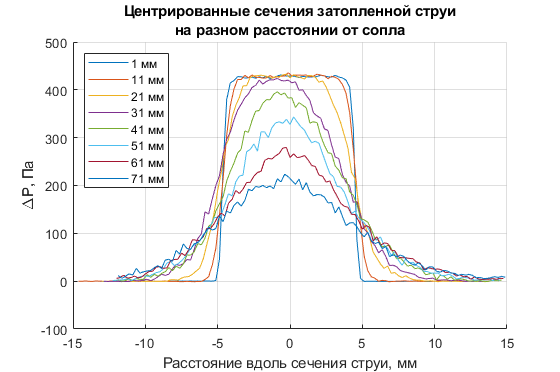

set(f3, 'Visible', 'on');

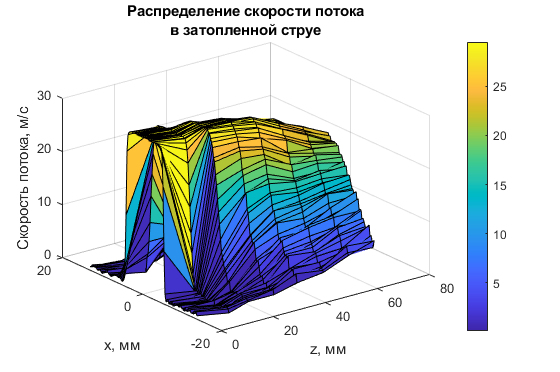


%Скорость

z01 = ones(length(p01), 1)*1;
z11 = ones(length(p11), 1)*11;
z21 = ones(length(p21), 1)*21;
z31 = ones(length(p31), 1)*31;
z41 = ones(length(p41), 1)*41;
z51 = ones(length(p51), 1)*51;
z61 = ones(length(p61), 1)*61;
z71 = ones(length(p71), 1)*71;

v01 = sqrt(2*abs(p01));
v11 = sqrt(2*abs(p11));
v21 = sqrt(2*abs(p21));
v31 = sqrt(2*abs(p31));
v41 = sqrt(2*abs(p41));
v51 = sqrt(2*abs(p51));
v61 = sqrt(2*abs(p61));
v71 = sqrt(2*abs(p71));

zAll = [z01, z11, z21, z31, z41, z51, z61, z71];
vAll = [v01, v11, v21, v31, v41, v51, v61, v71];

f4 = figure();
surf(zAll, xCentered, vAll);

title({'Распределение скорости потока', 'в затопленной струе'});
colorbar
zlabel('Скорость потока, м/c');
ylabel('x, мм');
xlabel('z, мм');
saveas(f4, "Скорость.png");
set(f4, 'Visible', 'on');

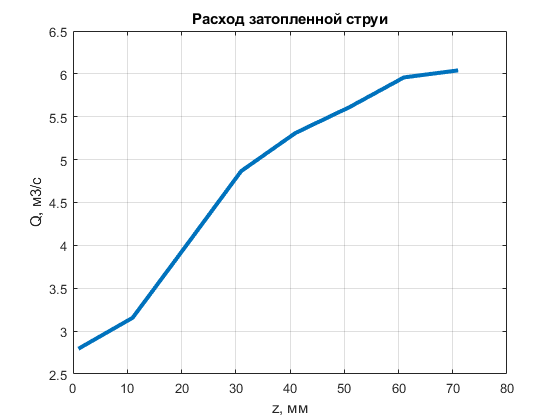


%Расход

S = vAll.*abs(xCentered);
Q = ones(8, 1)*0;
k = 2*pi* 1.2 * dx / 1000;
for j = 1:8
    for i = 1:(size(v01)-1)
        
        Q(j) = Q(j) + k*(S(i+1, j)+S(i, j))*(x(i+1) - x(i));
        
    end
end

f5 = figure;
d = z';
plot(d, Q, 'LineWidth', 3);
grid on;
title('Расход затопленной струи');
xlabel('z, мм');
ylabel('Q, м3/с')
set(f5, 'Visible', 'on');
saveas(f5, "Расход.png");